# Module 1

## Plant Model

G = plant_tf()

G =
 
                        
                9.229e04
                        
  -------------------------------------
                                       
  s^4 + 54.62 s^3 + 1306 s^2           
                                       
                           + 1.919e04 s
                                       
 
Continuous-time transfer function.




% Zeros and Poles of Plant
z = zero(G)


z =

  0×1 empty double column vector



p = pole(G)

p =    0.0000 + 0.0000i
 -32.6173 + 0.0000i
 -10.9998 +21.6179i
 -10.9998 -21.6179i



% ZPK Representation
zpk(G)  

ans =
 
               92289
  -------------------------------
  s (s+32.62) (s^2 + 22s + 588.3)
 
Continuous-time zero/pole/gain model.




% Natural frequency and damping ratio
damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00                -1.00e+00       0.00e+00              Inf    
 -1.10e+01 + 2.16e+01i     4.53e-01       2.43e+01         9.09e-02    
 -1.10e+01 - 2.16e+01i     4.53e-01       2.43e+01         9.09e-02    
 -3.26e+01                 1.00e+00       3.26e+01         3.07e-02    



% Step Response
step(G);

% Impulse Response
impulse(G);

% Bode diagram of Plant Model
bode(G);

## Closed-loop TFs

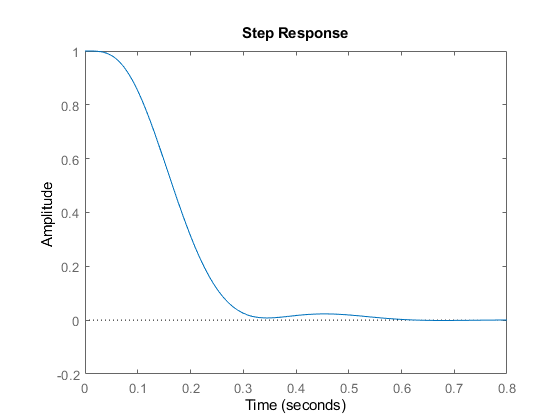

% Proportional Controller Gain
%   * Vary this variable and run the section to see the effect on closed loop
%     response.
K = 1.2;

% Closed loop TFs
[S, U, T, V, stability] = closed_loop_tfs(K);

% Plot the step responses of the closed-loop system (as 2 by 2 subplot)
%   - from reference signal to the output
%   - from reference signal to the control signal (plant input)
%   - from reference signal to the tracking error signal (the input of the controller) 
%   - from disturbance signal to the output
step(S)


% Closed-loop poles
% eg: cl_poles = poles(...);
cl_poles = [];

## Ultimate Gain Calculations by Routh Stability Criterion

#### Show the calculations to find ultimate gain using routh stability criterion in this section.

eg: $K_u =0$ (Use `Insert -> Equation` to add equations in text) 

## Closed-loop Step Response

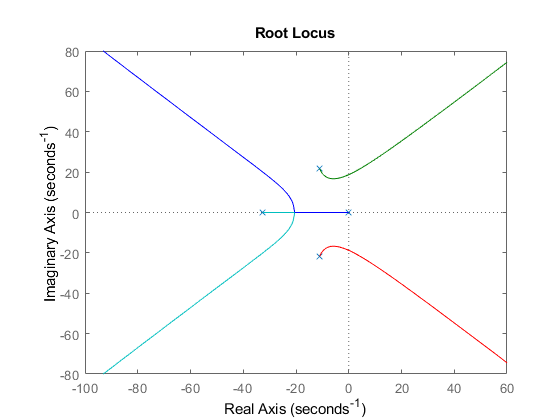

Ku = 0.4720

Ku = ultimate_gain()

K = 0.6 * Ku;

[S, U, T, V] = closed_loop_tfs(K);

% Calculate rise time, settling time and the overshoot using `stepinfo`
% Compute the closed-loop bandwidth using `bandwidth`
[rise_time, settling_time, overshoot, closedloop_bw] = closedloop_step_response(K)

Unrecognized function or variable 'bandwitdh'.

Error in closedloop_step_response (line 30)
closedloop_bw = bandwitdh(T + V);